# RawEMG2EMG

## 0. Visualize Raw Data

clc;
clear;
load('./RawData/structs/20250721_171032_swallow_JET_20250721_Trl002.mat');

% Display data information
FsEMG = Fs;
tEMG = time;
clear Fs;
clear time;
fprintf('Data loaded successfully:\n');

Data loaded successfully:


fprintf('- Sampling frequency: %d Hz\n', FsEMG);

- Sampling frequency: 2500 Hz


fprintf('- Signal length: %.2f seconds\n', length(L_MASS)/FsEMG);

- Signal length: 129.70 seconds


fprintf('- Number of samples: %d\n', length(L_MASS));

- Number of samples: 324250


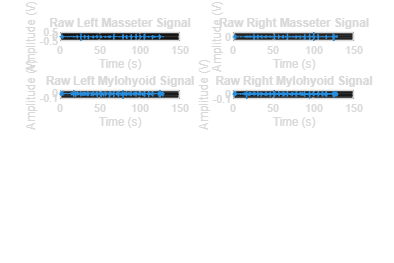


figure('Position', [100, 100, 1200, 800]);
subplot(4,2,1);
plot(tEMG, L_MASS);
title('Raw Left Masseter Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(4,2,2);
plot(tEMG, R_MASS);
title('Raw Right Masseter Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(4,2,3);
plot(tEMG, L_MYLO);
title('Raw Left Mylohyoid Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

subplot(4,2,4);
plot(tEMG, R_MYLO);
title('Raw Right Mylohyoid Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

## Process Each Muscle Signal

fprintf('\nProcessing EMG signals...\n');


Processing EMG signals...



try
    [L_MASS_filtered, L_MASS_envelope] = preprocess_emg_us(L_MASS, FsEMG);
    fprintf('✓ Left Masseter processed successfully\n');
catch ME
    fprintf('✗ Error processing Left Masseter: %s\n', ME.message);
    % Assign empty arrays to each variable separately
    L_MASS_filtered = [];
    L_MASS_envelope = [];
end

✓ Left Masseter processed successfully



try
    [R_MASS_filtered, R_MASS_envelope] = preprocess_emg_us(R_MASS, FsEMG);
    fprintf('✓ Right Masseter processed successfully\n');
catch ME
    fprintf('✗ Error processing Right Masseter: %s\n', ME.message);
    % Assign empty arrays to each variable separately
    R_MASS_filtered = [];
    R_MASS_envelope = [];
end

✓ Right Masseter processed successfully



try
    [L_MYLO_filtered, L_MYLO_envelope] = preprocess_emg_us(L_MYLO, FsEMG);
    fprintf('✓ Left Mylohyoid processed successfully\n');
catch ME
    fprintf('✗ Error processing Left Mylohyoid: %s\n', ME.message);
    L_MYLO_filtered = [];
    L_MYLO_envelope = [];
end

✓ Left Mylohyoid processed successfully



try
    [R_MYLO_filtered, R_MYLO_envelope] = preprocess_emg_us(R_MYLO, FsEMG);
    fprintf('✓ Right Mylohyoid processed successfully\n');
catch ME
    fprintf('✗ Error processing Right Mylohyoid: %s\n', ME.message);
    R_MYLO_filtered = [];
    R_MYLO_envelope = [];
end

✓ Right Mylohyoid processed successfully


## Visualize Processed Results

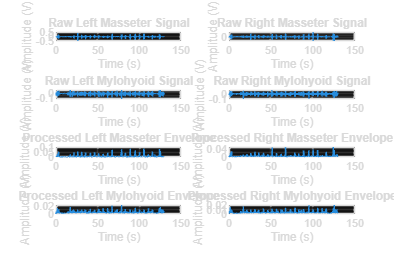

if ~isempty(L_MASS_envelope)
    subplot(4,2,5);
    plot(tEMG, L_MASS_envelope);
    title('Processed Left Masseter Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

if ~isempty(R_MASS_envelope)
    subplot(4,2,6);
    plot(tEMG, R_MASS_envelope);
    title('Processed Right Masseter Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

if ~isempty(L_MYLO_envelope)
    subplot(4,2,7);
    plot(tEMG, L_MYLO_envelope);
    title('Processed Left Mylohyoid Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

if ~isempty(R_MYLO_envelope)
    subplot(4,2,8);
    plot(tEMG, R_MYLO_envelope);
    title('Processed Right Mylohyoid Envelope');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

## Save Results

fprintf('\nSaving processed data...\n');


Saving processed data...


save('./ProcessedData/EMG_03.mat', 'L_MASS_filtered', 'L_MASS_envelope', ...
    'R_MASS_filtered', 'R_MASS_envelope', ...
    'L_MYLO_filtered', 'L_MYLO_envelope', ...
    'R_MYLO_filtered', 'R_MYLO_envelope', ...
    'tEMG', 'FsEMG');
fprintf('✓ Data saved to EMG_01.mat\n');

✓ Data saved to EMG_01.mat


## Optional: Display Signal Statistics

fprintf('\nSignal Statistics:\n');


Signal Statistics:


if ~isempty(L_MASS_envelope)
    fprintf('Left Masseter - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(L_MASS_envelope), std(L_MASS_envelope), max(L_MASS_envelope));
end

Left Masseter - Mean: 0.0067 V, Std: 0.0119 V, Max: 0.0830 V


if ~isempty(R_MASS_envelope)
    fprintf('Right Masseter - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(R_MASS_envelope), std(R_MASS_envelope), max(R_MASS_envelope));
end

Right Masseter - Mean: 0.0046 V, Std: 0.0053 V, Max: 0.0495 V


if ~isempty(L_MYLO_envelope)
    fprintf('Left Masseter - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(L_MYLO_envelope), std(L_MYLO_envelope), max(L_MYLO_envelope));
end

Left Masseter - Mean: 0.0037 V, Std: 0.0026 V, Max: 0.0238 V


if ~isempty(R_MYLO_envelope)
    fprintf('Right Masseter - Mean: %.4f V, Std: %.4f V, Max: %.4f V\n', ...
        mean(R_MYLO_envelope), std(R_MYLO_envelope), max(R_MYLO_envelope));
end

Right Masseter - Mean: 0.0038 V, Std: 0.0021 V, Max: 0.0203 V


function [signal_filtered, emg_envelope] = preprocess_emg_us(emg_signal, FsEMG)
    % This function preprocesses raw EMG signal recorded in a 60Hz environment.
    % It includes DC removal, notch filter, band-pass filter, rectification, and envelope detection.
    %
    % INPUTS:
    % emg_signal - The raw EMG data vector (column or row vector)
    % FsEMG - The sampling frequency of the signal
    %
    % OUTPUT:
    % emg_envelope - The processed linear envelope of the EMG signal
    %
    % Processing steps:
    % 1. DC offset removal
    % 2. Notch filter (60 Hz powerline interference)
    % 3. Band-pass filter (20-450 Hz for EMG frequency range)
    % 4. Full-wave rectification
    % 5. Envelope extraction via low-pass filtering
    
    % Ensure signal is a column vector
    if isrow(emg_signal)
        emg_signal = emg_signal';
    end
    
    % Check for valid inputs
    if FsEMG <= 0
        error('Sampling frequency must be positive');
    end
    if length(emg_signal) < 100
        warning('Signal is very short, filtering may not be reliable');
    end
    
    % 1. DC Offset Removal
    signal_detrended = detrend(emg_signal, 'constant');
    
    % 2. Notch Filter (60 Hz)
    f_notch = 60; % Powerline frequency (Hz)
    wo = f_notch / (FsEMG/2); % Normalized frequency
    
    % Check if notch frequency is valid
    if wo >= 1
        warning('Notch frequency too high for given sampling rate. Skipping notch filter.');
        signal_notched = signal_detrended;
    else
        % Manual notch filter implementation (alternative to iirnotch)
        % Design a 2nd-order IIR notch filter
        r = 0.95; % Pole radius (closer to 1 = narrower notch)
        
        % Calculate filter coefficients
        b_notch = [1, -2*cos(pi*wo), 1];
        a_notch = [1, -2*r*cos(pi*wo), r^2];
        
        % Apply the notch filter
        signal_notched = filtfilt(b_notch, a_notch, signal_detrended);
    end
    
    % 3. Band-pass Filter (20-450 Hz)
    f_low = 20; % Low cutoff (Hz) - removes motion artifacts
    f_high = 450; % High cutoff (Hz) - matches your specification
    order_band = 4; % 4th-order Butterworth filter
    
    % Normalize frequencies
    wn = [f_low, f_high] / (FsEMG/2);
    
    % Check if frequencies are valid
    if any(wn >= 1)
        error('Cutoff frequencies must be less than Nyquist frequency (%.1f Hz)', FsEMG/2);
    end
    
    [b_band, a_band] = butter(order_band, wn, 'bandpass');
    signal_filtered = filtfilt(b_band, a_band, signal_notched);
    
    % 4. Full-wave Rectification
    signal_rectified = abs(signal_filtered);
    
    % 5. Envelope Extraction (Low-pass Filter at 6 Hz)
    f_cutoff_envelope = 6; % Envelope cutoff frequency (Hz)
    order_envelope = 4; % 4th-order Butterworth filter
    
    % Normalize frequency
    wn_env = f_cutoff_envelope / (FsEMG/2);
    
    if wn_env >= 1
        error('Envelope cutoff frequency too high for given sampling rate');
    end
    
    [b_low, a_low] = butter(order_envelope, wn_env, 'low');
    emg_envelope = filtfilt(b_low, a_low, signal_rectified);
    
    % Convert back to row vector if input was row vector
    if isrow(emg_signal)
        emg_envelope = emg_envelope';
    end

end